## Zdvihový objem, kompresní objem, kompresní poměr

 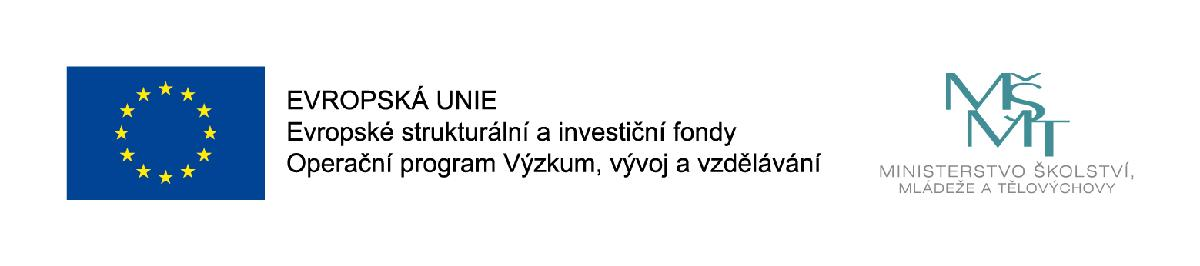

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

#### www: [http://bit.ly/termomechanika_online/](http://bit.ly/termomechanika_online/)

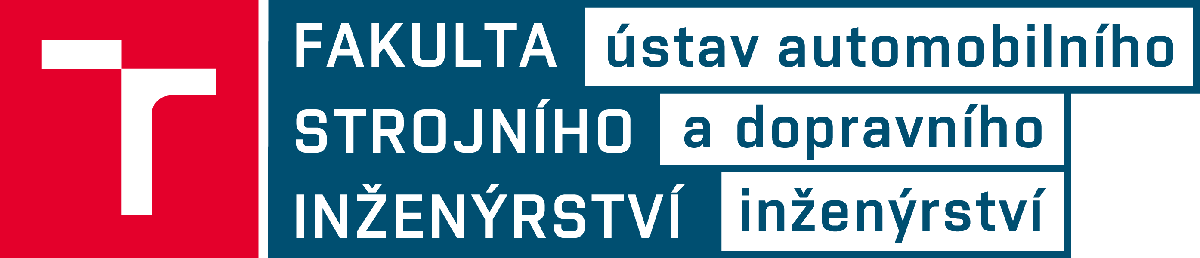

## Zdvihový objem

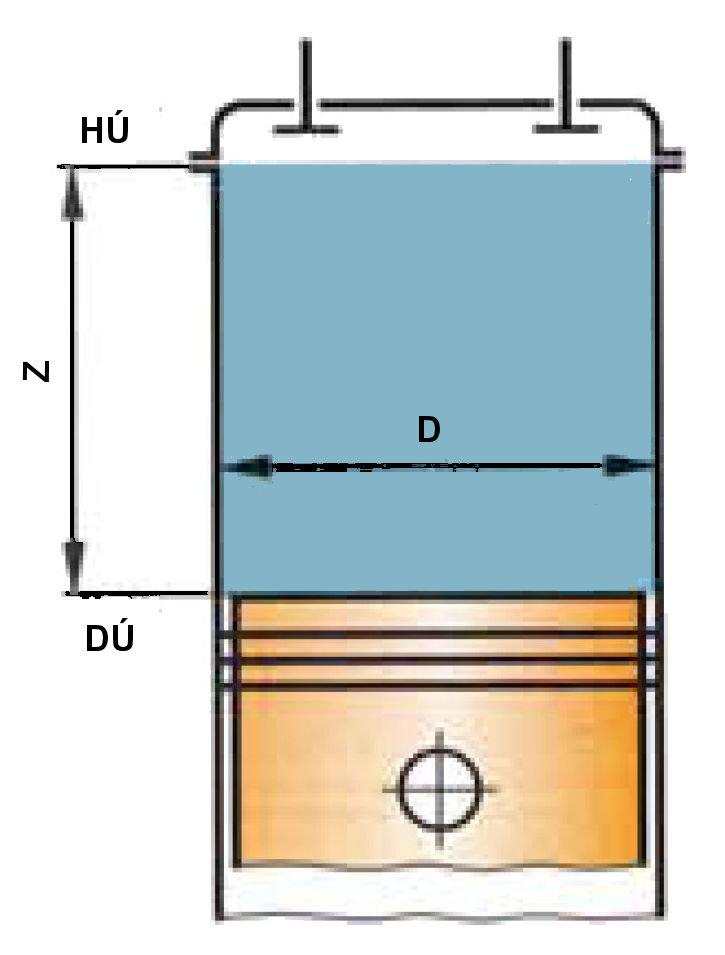

D        [mm]    prúměr válce; vrtání

Z        [mm]    zdvih

$V_Z$      [$cm^3$]    zdvihový objem

Z         [-]          počet válců

$V_{ZM}$    [$cm^3$]    zdvihový objem motoru

S        [mm2]    plocha/průřez válce


$$V_Z=\frac{\pi \cdot D^2}{4} \cdot Z = S \cdot Z$$



$$V_{ZM} = V_Z \cdot z$$


D = 84.0;    % [mm]    prúměr válce; vrtání
Z = 80.0;    % [mm]    zdvih
z = 4;       % [-]     počet válců
VZ = pi * mm2m(D)^2 / 4.0 * mm2m(Z);
VZcm3 = m32cm3(VZ)

VZcm3 = 443.3416

VZM = VZ * z;
VZMcm3 = m32cm3(VZM)

VZMcm3 = 1.7734e+03

## Kompresní objem, kompresní poměr

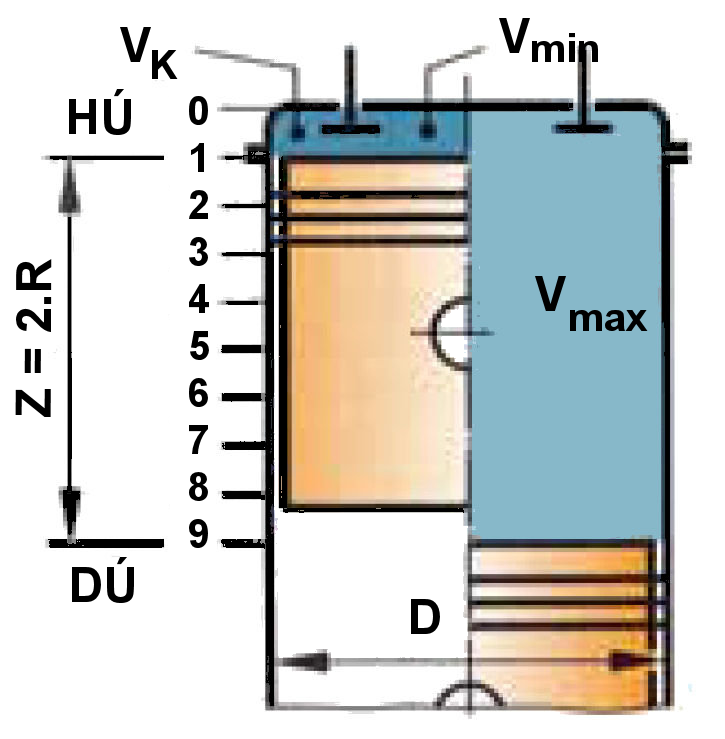

$\epsilon$           [-]     kompresní poměr

$V_K$        [$cm^3$]     kompresní onjem

V           [$cm^3$]     objem válce; spalovací prostor

$V_{min}$      [$cm^3$]     minimální objem válce; spalovací prostor        $V_{min} = V_K$

$V_{max}$      [$cm^3$]     maximálni objem válce; spalovací prostor        $V_{max} = V_K + V_Z$


$$\epsilon = \frac{V_{max}}{V_{min}}=\frac{V_K+V_Z}{V_K}$$



$$V_Z = V_K \cdot (\epsilon-1)$$



$$V_K = V_{min} = \frac{V_Z}{\epsilon-1}$$



$$V_{max} = V_Z + V_K$$


Typické hodnoty kompresního poměru pro zážehové motory    $\epsilon = 7 \sim15$

Typické hodnoty kompresního poměru pro vznětové motory    $\epsilon = 14 \sim25$

VZcm3 = 320.0;
VZ = cm32m3(VZcm3);
VKcm3 = 40.0;
VK = cm32m3(VKcm3);
eps = (VK+VZ)/VK

eps = 9

## Zdvihový poměr

k        [-]             zdvihový poměr

Z        [mm]         zdvih

D        [mm]     průměr válce (vrtání)

Typické hodnoty pro zážehový motor     $k = 0,7 \sim1,2$

Typické hodnoty pro vznětový motor     $k = 0,8 \sim1,3$

Nadčtvercový motor $Z > D$    $k > 1$

Čtvercový motor $Z = D$    $k = 1$

Podčtvercový motor $Z < D$    $k < 1$

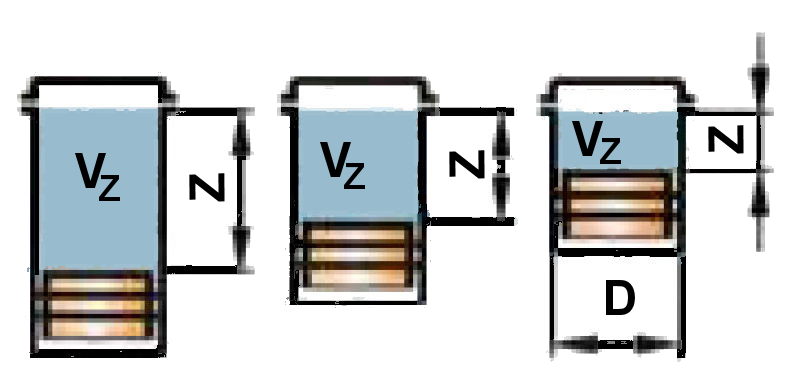

## Délka ojnice

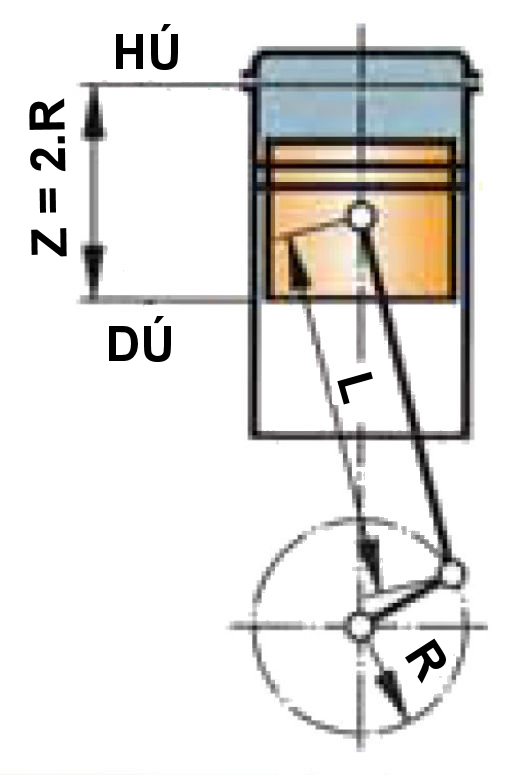

$\lambda_L$    [-]        poměr klika ojnice

$Z$    [mm]    zdvih

$L$    [mm]    délka ojnice

$R$    [mm]    poloměr kliky


$$\lambda_L = \frac{R}{L}$$


Typická hodnota pro zážehové motory  $\lambda_L = 0,21 \sim 0,31$

Typická hodnota pro vznětové motory  $\lambda_L = 0,22 \sim 0,33$


$$Z=2 \cdot R$$


Zdvih 80 mm a délka ojnice 125 mm

Z = 80.0; % [mm] zdvih
L = 125.0; % [mm] délka ojnice
R = Z / 2.0;
LambdaL = R/L

LambdaL = 0.3200

## Dráha pístu

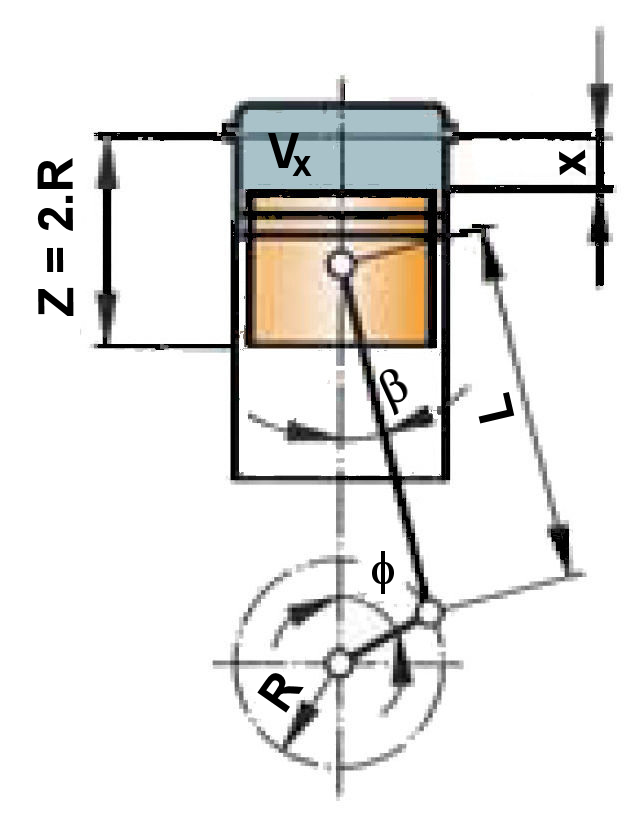

x        [mm] dráha pístu

L         [mm]

R        [mm]

$\phi$ ($\alpha$)  [°]

$\beta$        [°]


$$x = R \cdot \big(1-cos \phi \big)+L \cdot \big(1-cos \beta \big)$$



$$L \cdot sin \beta = R \cdot sin \phi$$



$$cos \beta = \sqrt{1-sin^2\beta} = \sqrt{1- \big(\frac{R}{L}\big)^2sin^2\phi}$$



$$x = R \cdot \big(1-cos \phi \big)+L \cdot \big(1-\sqrt{1- \big(\frac{R}{L}\big)^2sin^2\phi} \big)$$


Vypočtěte polohu pístu jeli úhel klikového hřídele 30° poloměr kliky 39 mm, délka ojnice 150 mm

phi = 30.0;
R = 39.0;
L = 150.0;

beta = acosd(sqrt(1-(R/L)^2*sind(phi)^2))

beta = 7.4696


x = R * (1-cosd(phi)+L * (1-sqrt(1-(R/L)^2*sind(phi)^2)))

x = 54.8681

x = R * (1-cosd(phi) + L * (1-cosd(beta)))

x = 54.8681

## Změna kompresního poměru

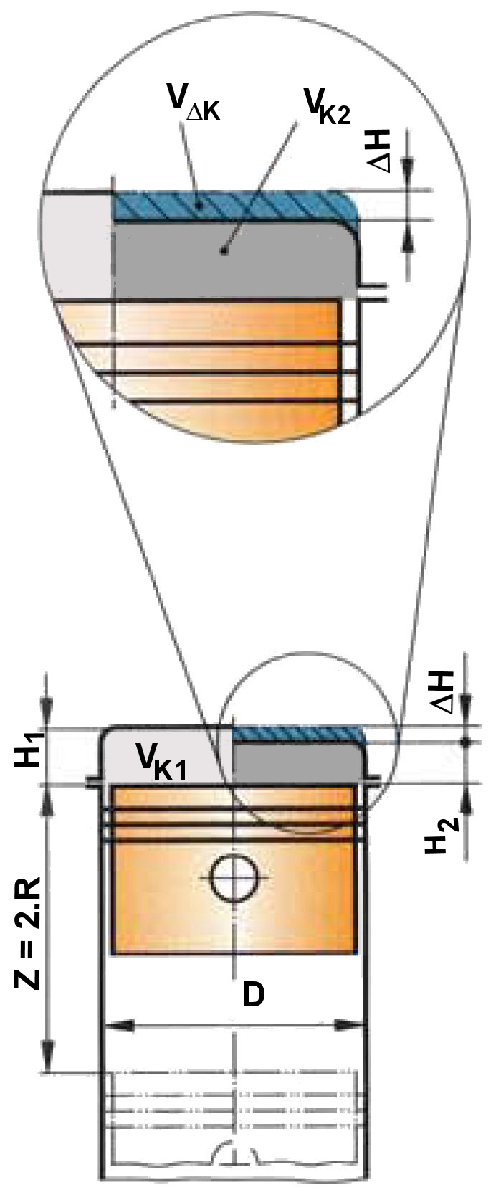

$V_{K1}$    [ccm]    výchozí kompresní objem

$V_{K1}$    [ccm]    změněný kompresní objem

$\epsilon_1$        [-]        výchozí kompresní poměr

$\epsilon_2$        [-]        změněný kompresní poměr

$H_1$        [mm]    původní výška kompresního prostoru

$H_2$        [mm]    změněná výška kompresního prostoru

$\Delta H$    [mm]        změna výšky kompresního prostoru

Zvýšení kompresního poměru $\Delta H = \frac{Z}{\epsilon_1-1} -\frac{Z}{\epsilon_2-1}$

Snížení kompresního poměru $\Delta H = \frac{Z}{\epsilon_2-1} -\frac{Z}{\epsilon_1-1}$

Kompresní poměr 8,7, požadovaný nový kompresní poměr 9,3, zdvih 80 mm o koli musíme změnit výšku kompresního poměru,

epsilon1 = 8.7;
epsilon2 = 9.3;
Z = 80.0;             % [mm] zdvih
deltaH = Z/(epsilon1-1)-Z/(epsilon2-1)

deltaH = 0.7511

# Funkce

% Univerzální plynová konstanta

function [result] = Rm
   result = 8314.3;              
end   
% Převádí teplotu ve stupních Celsia na Kelvíny
function [K] = C2K(C)
K = C+273.15;
end
% Převádí hektopascaly na Pascaly
function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 
% Převádí hektopascaly na Pascaly
function [Pa] = MPa2Pa(MPa)
Pa = MPa*10^6;
end 
% Převádí hektopascaly na Pascaly
function [Pa] = kPa2Pa(kPa)
Pa = kPa*10^3;
end 
% Převod litrů
function [m3] = l2m3(l)
m3 = l*.001;
end
% Převod ccm
function [cm3] = m32cm3(m3)
cm3 = m3 * 1000000;
end
% Převod ccm
function [m3] = cm32m3(cm3)
m3 = cm3 / 1000000;
end
% Převod litrů
function [l] = m32l(m3)
l = m3 /0.001;
end
% Převod Pascalů
function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end
% Převod Watů
function [kW] = W2kW(W)
kW = W/1000;
end
% Převod
function [mm] = m2mm(m)
mm = m*1000;
end
% Převod
function [m] = mm2m(mm)
m = mm / 1000;
end
% Převod
function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end
%Převod 
function [res] = MPa
    res = 10000000.0;
end
%Převod 
function [bar] = Pa2bar(Pa)
    bar = Pa/100000;
end
% Převod jednotek pressure from bar to pascals.
function [Pa] = bar2Pa(bar)
    Pa = bar*100000;
end
% Převod jednotek temperature from Kelvin to degrees Celsius.
function [C] = K2C(K)
    C = K-273.15;
end